# **Solving Differential Equations Numerically**

## Example 1: RC Circuit (Step Input)

Given: R = 1 kΩ, C = 100 μF, Vin = 5 V, Vc(0) = 0, simulate t ∈ [0,1] s

Equation: dVc/dt = (Vin - Vc)/(RC)

MATLAB Code:

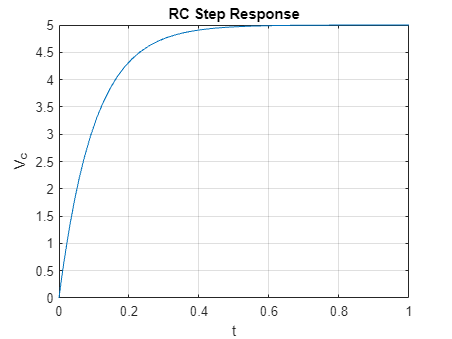

R=1e3; C=100e-6; Vin=5;
f=@(t,Vc)(Vin - Vc)/(R*C);
[t,Vc]=ode45(f,[0 1],0);
plot(t,Vc), grid on, title('RC Step Response'), xlabel t, ylabel V_c

## **Example 2: RL Circuit (Step Input)**

Given: R = 10 Ω, L = 0.5 H, Vin = 12 V, i(0) = 0, simulate t ∈ [0,5] s

Equation: di/dt = (Vin - Ri)/L

MATLAB Code:

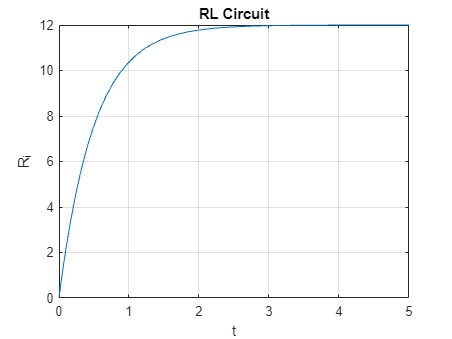

R=10; L=0.5; Vin=12; t=[0 5];
f=@(t,Ri) (Vin - Ri)/L;
[t,Ri]=ode45(f,t,0);
plot(t,Ri), grid on, title('RL Circuit'), xlabel t, ylabel R_i

## Example 3: Newton’s Law of Cooling

Given: k = 0.3 s⁻¹, T∞ = 25 °C, T(0) = 90 °C, simulate t ∈ [0,20] min

Equation: dT/dt = -k(T - T∞)

MATLAB Code:

k=0.3; Tinf=298; T0=363; t=[0 1200]

t =            0        1200


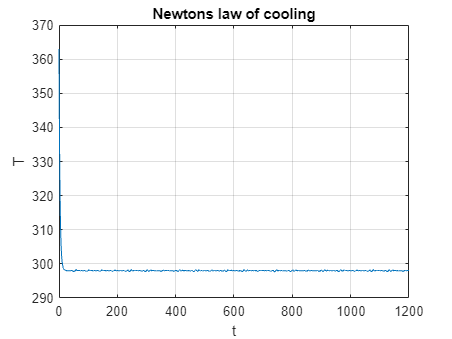

f=@(t,T) [-k*(T - Tinf)];
[t,T]=ode45(f,t,T0);
plot(t,T), grid on, title('Newtons law of cooling'), xlabel t, ylabel T

## **Example 4: Tank Draining (Torricelli)**

Given: g = 9.81 m/s², outlet a = 2e-4 m², tank area At = 0.05 m², h(0) = 1.2 m, simulate t ∈ [0,200] s

Equation: dh/dt = -(a/At)√(2gh)

MATLAB Code:

g=9.81; a=2e-4; At=0.05; h0=1.2; t=[0 200];
f= @(t,h) -(a/At)*sqrt(2*g*h);
[t,h]=ode45 (f,t,h0)

t =          0
    3.1061
    6.2121
    9.3182
   12.4243
   17.4243
   22.4243
   27.4243
   32.4243
   37.4243


h =    1.2000 + 0.0000i
   1.1405 + 0.0000i
   1.0825 + 0.0000i
   1.0260 + 0.0000i
   0.9710 + 0.0000i
   0.8856 + 0.0000i
   0.8042 + 0.0000i
   0.7267 + 0.0000i
   0.6532 + 0.0000i
   0.5836 + 0.0000i


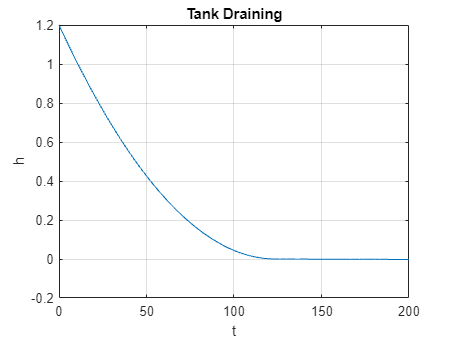

plot(t,h), grid on, title('Tank Draining'), xlabel t, ylabel h

## Example 5: Mixing Tank (Constant Volume)

Given: F = 1 L/min, V = 10 L, Cin = 2 mol/L, C(0) = 0, simulate t ∈ [0,30] min

Equation: dC/dt = (F/V)(Cin - C)

MATLAB Code:

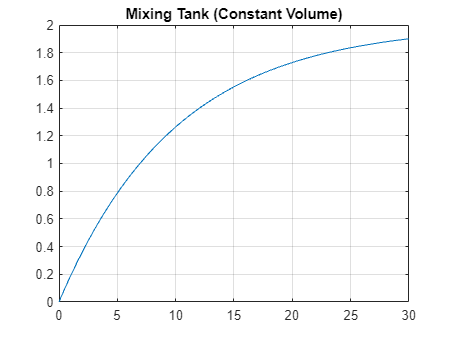

F=1; V=10; Cin=2; C0=0; t=[0 30];
f= @(t,C) (F/V)*(Cin - C);
[t,C]= ode45(f,t,C0);
plot(t,C), grid on, title('Mixing Tank (Constant Volume)')

## **Example 6: First-Order Reaction in Batch**

Given: k = 0.4 min⁻¹, CA(0) = 1.5 mol/L, simulate t ∈ [0,20] min

Equation: dCA/dt = -k CA

MATLAB Code:

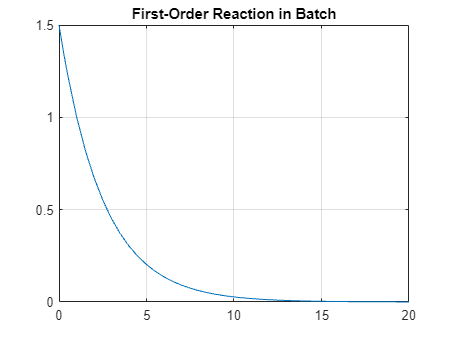

k=0.4; CA0=1.5; t=[0 20];
f= @(t,CA) -k*CA;
[t,CA]= ode45(f,t,CA0);
plot(t,CA), grid on, title('First-Order Reaction in Batch')

## Example 7: CSTR with Reaction

Given: F = 2 L/min, V = 20 L, CA,in = 1 mol/L, k = 0.2 min⁻¹, CA(0) = 0, simulate t ∈ [0,100] min

Equation: dCA/dt = (F/V)(CA,in - CA) - kCA

MATLAB Code:

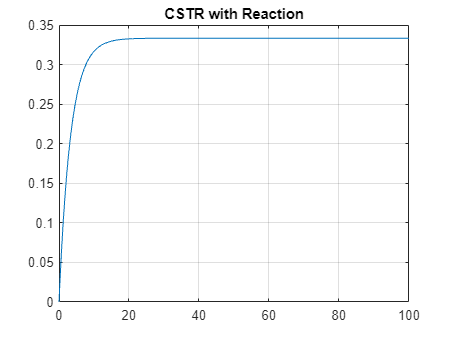

F=2; V=20; CAin=1; k=0.2; CA0=0; t=[0,100];
f= @(t,CA) (F/V)*(CAin - CA) - k*CA;
[t,CA]= ode45(f,t,CA0);
plot(t,CA), grid on, title('CSTR with Reaction')

## **Example 8: Heated Lumped Thermal Mass**

Given: m = 2 kg, cp = 4200 J/kgK, hA = 15 W/K, T∞ = 20 °C, Qin = 200 W, T(0) = 20 °C, simulate t ∈ [0,3600] s

Equation: dT/dt = (Qin - hA(T - T∞))/(m cp)

MATLAB Code:

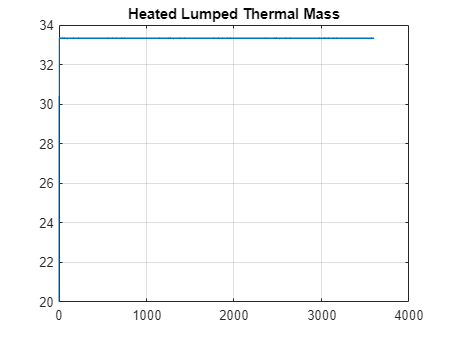

m=2; cp=4200; hA=15; Tinf=20; Qin=200; T0=20; t=[0 3600];
f= @(t,T) (Qin-hA*(T-Tinf));
[t,T] = ode45(f,t,T0);
plot(t,T), grid on, title('Heated Lumped Thermal Mass')

## Example 9: First-Order Lag (Control System)

Given: K = 2, τ = 3 s, step input u0 = 1, y(0) = 0, simulate t ∈ [0,20] s

Equation: dy/dt = (-y + K u0)/τ

MATLAB Code:

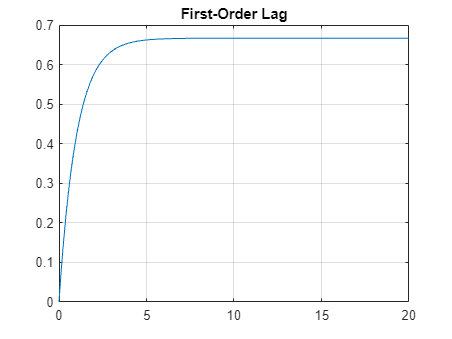

K=2; tau=3; u0=1; y0=0; t=[0 20];
f= @(t,y) -y + K*u0/tau;
[t,y]= ode45(f,t,y0);
plot(t,y), grid on, title('First-Order Lag')

## **Example 10: Logistic Growth with Harvesting**

Given: r = 0.8 yr⁻¹, K = 100, h = 0.2 yr⁻¹, x(0) = 5, simulate t ∈ [0,50] yr

Equation: dx/dt = r x(1 - x/K) - h x

MATLAB Code:

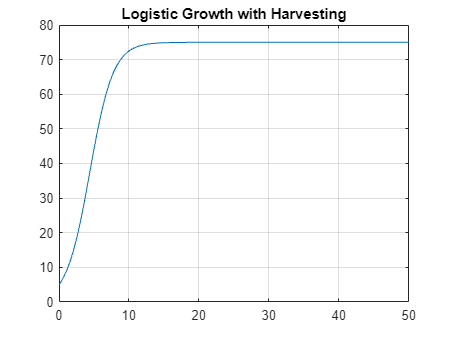

r=0.8; K=100; h=0.2; x0=5; t= [0 50];
f= @(t,x) r*x*(1-x/K)-h*x;
[t,x]=ode45(f,t,x0);
plot(t,x), grid on, title('Logistic Growth with Harvesting')

# Solving 2nd Order Differential Equations using ODE45 

Since `ode45` only works with **first-order systems**, every second-order ODE must first be rewritten as a system:

## **Example 11: Simple Harmonic Oscillator**

Equation: y'' + y = 0,  y(0)=1, y'(0)=0, t∈[0 20]

MATLAB Code:

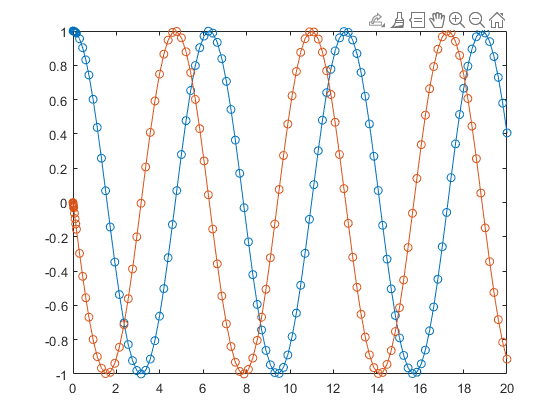

f = @(t,Y)[Y(2); -Y(1)];
ode45(f,[0 20],[1 0]);

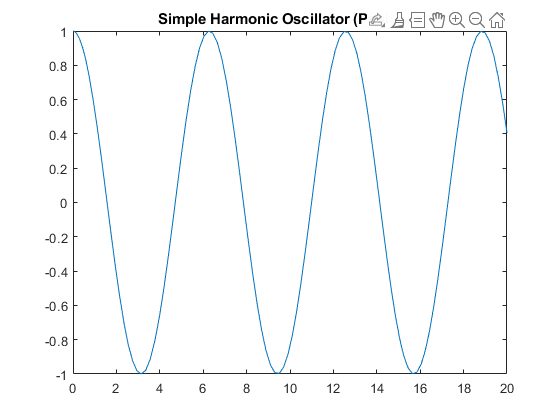

[t,Y] = ode45(f,[0 20],[1 0]);
plot(t,Y(:,1)), title('Simple Harmonic Oscillator (Position)')

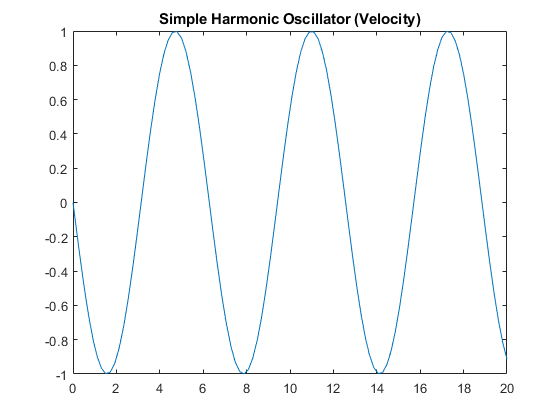

plot(t,Y(:,2)), title('Simple Harmonic Oscillator (Velocity)')

## Example 12: Damped Oscillator

Equation: y'' + 0.5y' + y = 0

y(0)=5, y'(0)=0, t∈[0 20]

MATLAB Code:

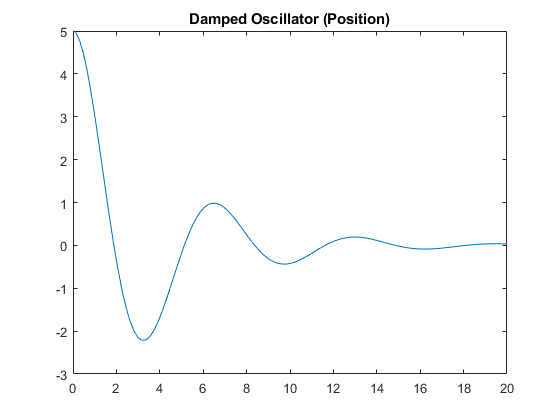

f= @(t,Y) [Y(2);-0.5*Y(2)-Y(1)];
[t,Y]=ode45(f,[0 20], [5 0]);
plot(t,Y(:,1)), title('Damped Oscillator (Position)')

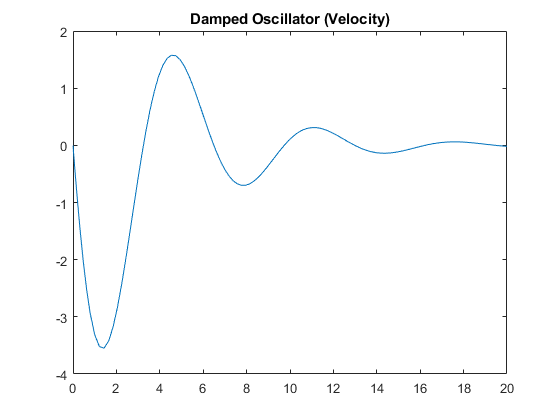

plot(t,Y(:,2)), title('Damped Oscillator (Velocity)')

## **Example 13: Forced Oscillator**

Equation: y'' + y = sin(t),  y(0)=0, y'(0)=1, t∈[0 20]

MATLAB Code:

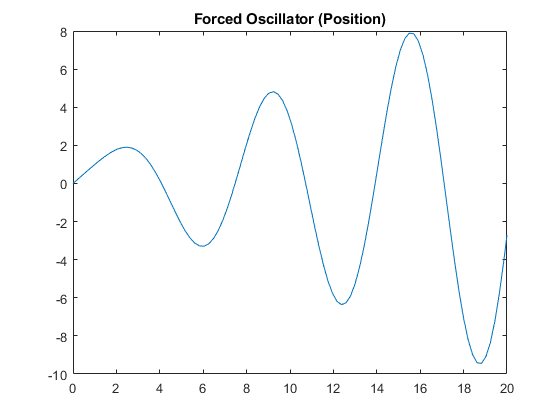

f= @(t,Y) [Y(2);-Y(1)+sin(t)];
[t,Y]=ode45(f,[0 20],[0 1]);
plot(t,Y(:,1)), title('Forced Oscillator (Position)')

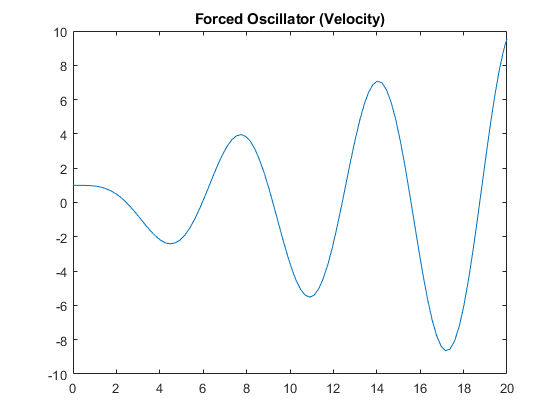

plot(t,Y(:,2)), title('Forced Oscillator (Velocity)')

## Example 14: Spring–Mass–Damper

Equation: y'' + 2y' + 5y = 0, t∈[0 10], y(0)=1, y'(0)=0

MATLAB Code:

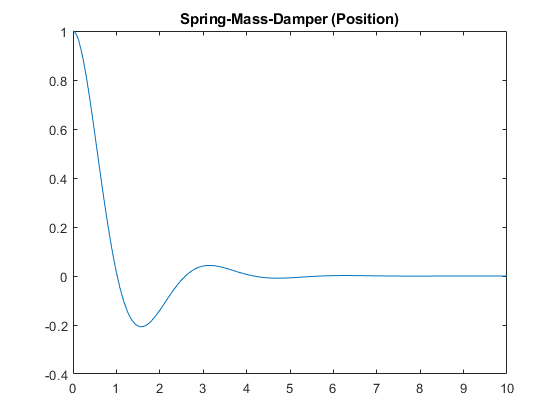

f= @(t,Y) [Y(2); -2*Y(2)-5*Y(1)];
[t,Y]= ode45(f,[0 10],[1 0]);
plot(t,Y(:,1)), title('Spring-Mass-Damper (Position)')

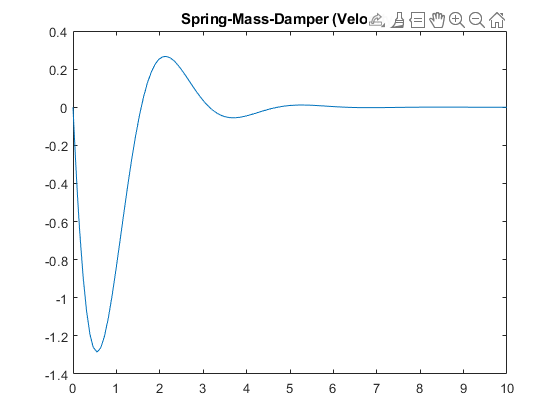

plot(t,Y(:,2)), title('Spring-Mass-Damper (Velocity)')

## **Example 15: Nonlinear Pendulum**

Equation: θ'' + sin(θ) = 0, t∈[0 20], θ(0)=0.10, θ'(0)=0

MATLAB Code:

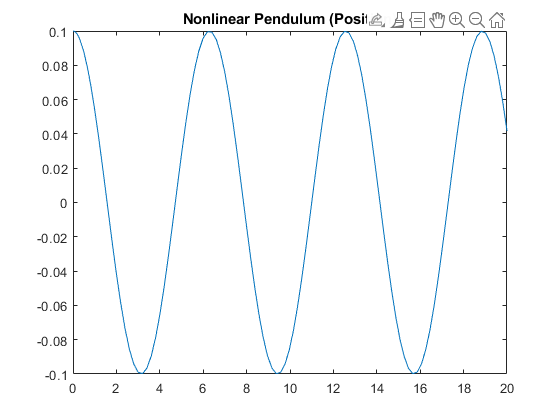

f=@(t,theta) [theta(2);-sin(theta(1))];
[t,theta]=ode45(f,[0 20],[0.1 0]);
plot(t,theta(:,1)), title('Nonlinear Pendulum (Position)')

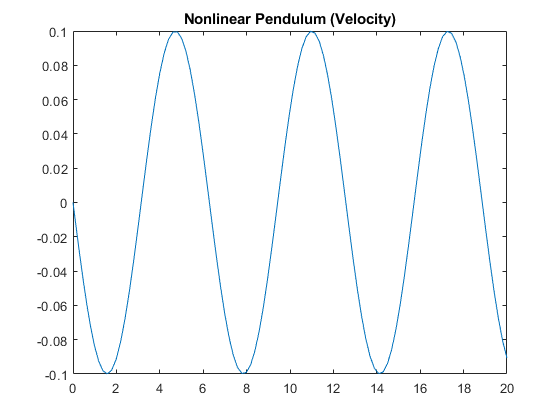

plot(t,theta(:,2)), title('Nonlinear Pendulum (Velocity)')

## Example 16: Driven Damped Pendulum

Equation: θ'' + 0.2θ' + sin(θ) = 0.5cos(t), t∈[0 50], y(0)=0, y'(0)= 0

MATLAB Code:

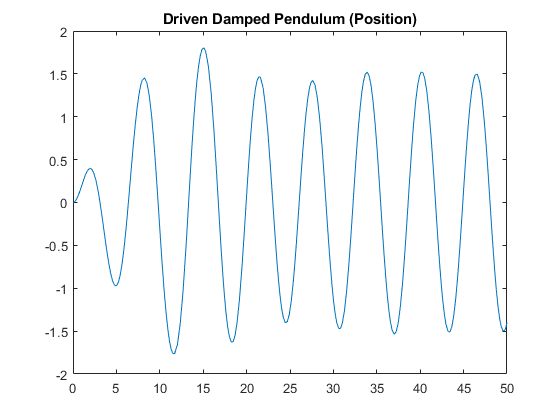

f=@(t,theta) [theta(2); -0.2*theta(2)-sin(theta(1))+0.5*cos(t)];
[t,theta]=ode45(f,[0 50],[0 0]);
plot(t,theta(:,1)), title('Driven Damped Pendulum (Position)')

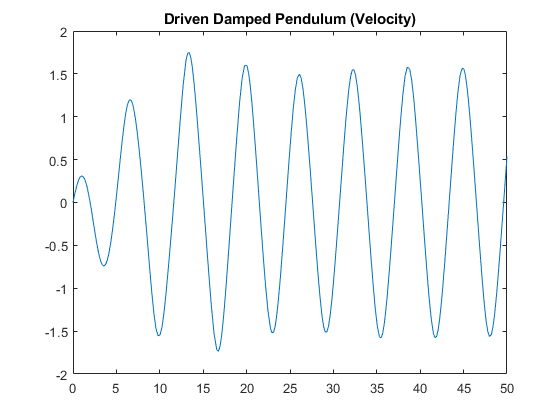

plot(t,theta(:,2)), title('Driven Damped Pendulum (Velocity)')

## **Example 17: RLC Circuit**

Equation: Lq'' + Rq' + q/C = sin(t),  L=1, R=2, C=0.5, t∈[0 20], y(0)=0, y'(0)= 0

MATLAB Code:

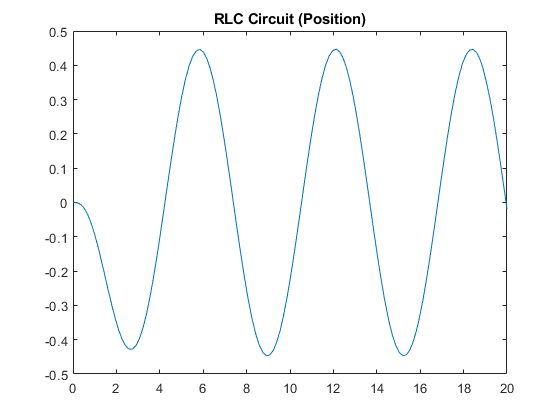

L=1; R=2; C=0.5;
f=@(t,q) [q(2);(-R*q(2)-q(1)/C-sin(t))/L];
[t,q]= ode45(f,[0 20],[0 0]);
plot(t,q(:,1)), title('RLC Circuit (Position)')

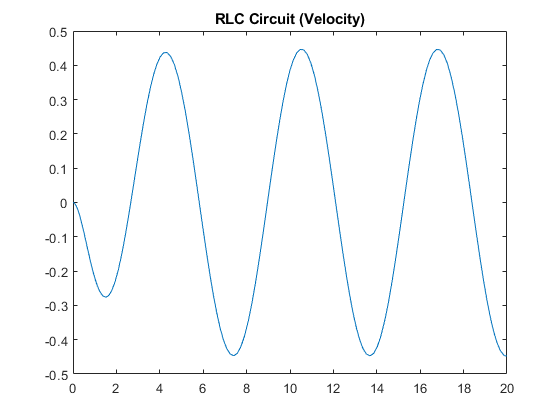

plot(t,q(:,2)), title('RLC Circuit (Velocity)')

## Example 18: Bungee Jumper (Nonlinear Damping)

Equation: y'' + 0.01(y')² + y = 0, t∈[0 30], y(0)=10, y'(0)= 0

MATLAB Code:

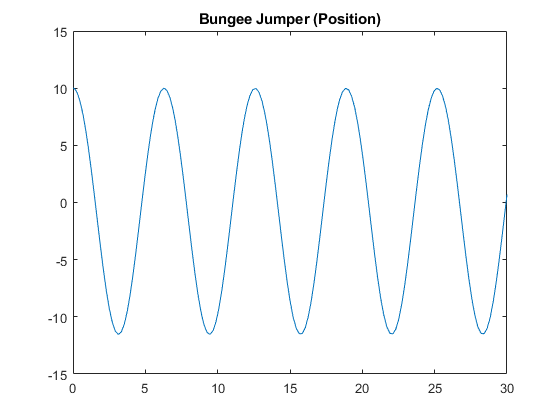

f=@(t,y) [y(2); -0.01*(y(2))^2-y(1)];
[t,y]= ode45(f,[0 30],[10 0]);
plot(t,y(:,1)), title('Bungee Jumper (Position)')

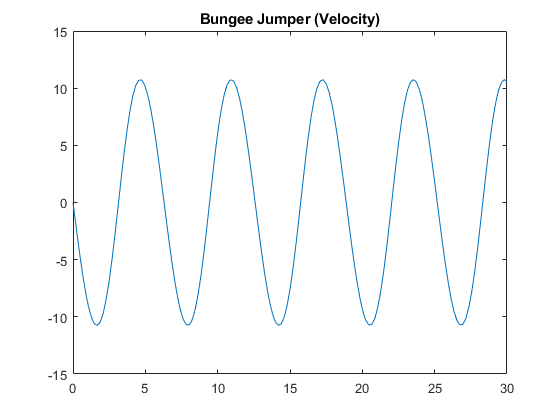

plot(t,y(:,2)), title('Bungee Jumper (Velocity)')

## Example 19: Beam Vibration with Forcing

Equation: y'' + 0.1y' + 3y = cos(2t), t∈[0 40], y0=0, y'(0)= 0

MATLAB Code:

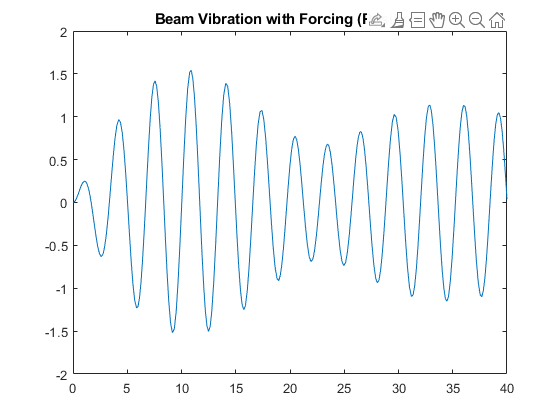

f=@(t,y) [y(2); -0.1*y(2)-3*y(1)+cos(2*t)];
[t,y]= ode15s(f,[0 40],[0 0]);
plot(t,y(:,1)), title('Beam Vibration with Forcing (Position)')

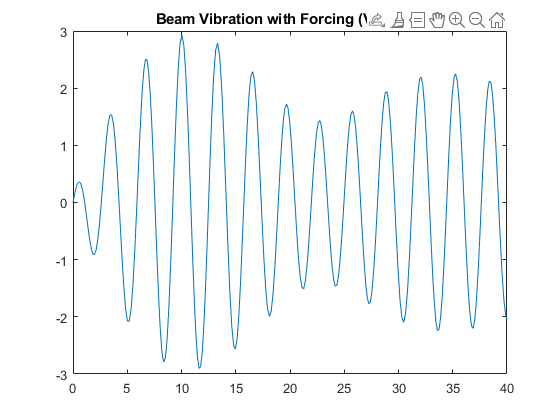

plot(t,y(:,2)), title('Beam Vibration with Forcing (Velocity)')

## **Example 20: Van der Pol Oscillator**

Equation: y'' - μ(1-y²)y' + y = 0,  μ=1, t∈[0 3000], y0=[2 0]

MATLAB Code:

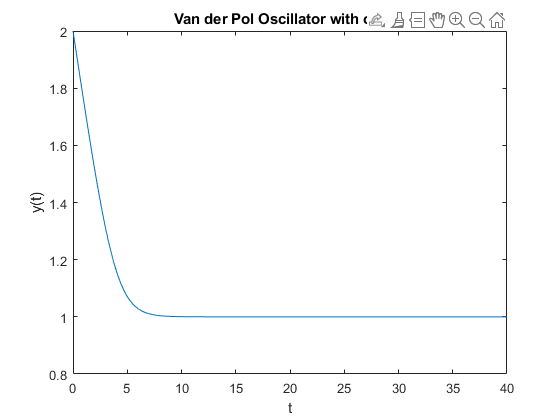

% Van der Pol equation (stiff for large mu)
mu = 1000;

 f = @(t,y) [y(2);mu*(1-(y(1)^2)*y(2)-y(1))];

% Initial conditions
y0 = [2; 0];
tspan = [0 3000];

% Solve with ode45 (non-stiff solver)
tic
try
    [t,y] = ode45(f,t,y0);
    plot(t,y(:,1))
    xlabel('t'); ylabel('y(t)')
    title('Van der Pol Oscillator with ode45')
catch ME
    disp('ode45 failed: system too stiff.')
end

toc

Elapsed time is 0.166317 seconds.


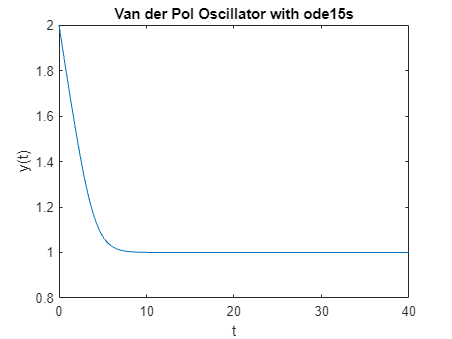


% Solve with ode15s (stiff solver)
tic
[t,y] = ode15s(f,t,y0);
figure
plot(t,y(:,1))
xlabel('t'); ylabel('y(t)')
title('Van der Pol Oscillator with ode15s')

toc

Elapsed time is 0.074842 seconds.
